# Analyis of theoretical and simulation results

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Single_Pipes
L_1=5000 um
L_1=211.98 um
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s



%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL=(Table_c_Pipe_1.Var2);

t=0:time_delta:time_simul;
%Mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_1*height_pipe);

%Peclet number, see [3, Eq. below 11]
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Circular channel: [1, Eq.(4.54) pp.77]
%D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

c=c_Tartrazine./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));


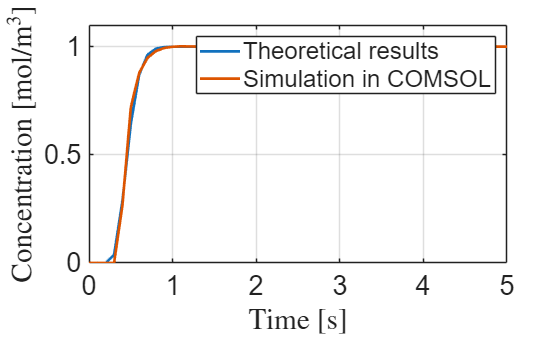

figure;
plot(t,c,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,c_COMSOL,'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(c)]);
legend('Theoretical results','Simulation in COMSOL')

### References

[1] H. Bruus, Theoretical Microfluidics. 2008. doi: 10.1093/oso/9780199235087.001.0001.  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, "Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section," Mathematical and Computer Modelling, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: 10.1016/j.mcm.2006.11.029. 

[4] Murat paper